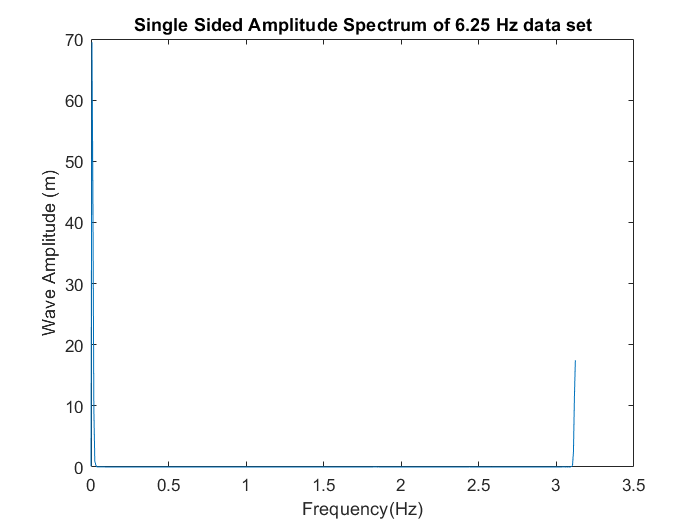

Textfile = load("PSD.txt");
writematrix(Textfile, "PSD.csv");
FFTData = readtable("PSD.csv");


N =  1024 - 1; 
FFTData = FFTData{:, 1}; %data is symmetric, *2 to account for contribution of other half 
fs = 6.25;
frequency = (fs*(0:(N/2))/(N));

plot(frequency(1:512), FFTData(1:512)); %only plotting the real side of the dataset 
title("Single Sided Amplitude Spectrum of 6.25 Hz data set");
xlabel("Frequency(Hz)");
ylabel("Wave Amplitude (m)");